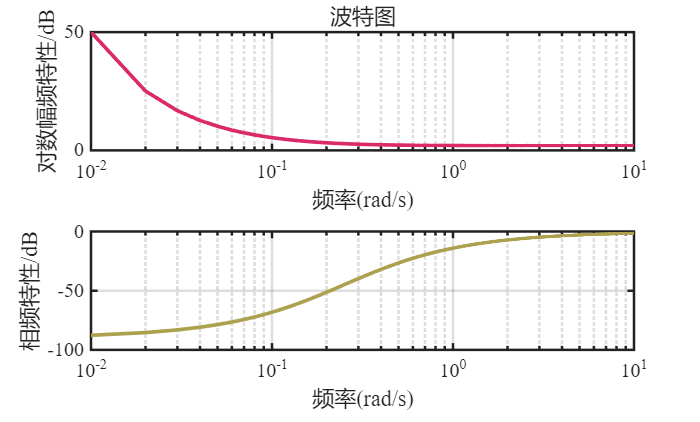

clc,clear,close all
tic
format long g
KP=2;
KI=0.5;
w=linspace(1e-2,10,1e3);
s=1j*w;
H=KP+KI./s;
subplot(2,1,1)
semilogx(w,abs(H),"LineWidth",2.2,"Color",[219 42 106]/255)
grid on;
xlabel('频率(rad/s)')
ylabel('对数幅频特性/dB')
title('波特图')
set(gca,'LineWidth',1.5,'FontSize',12);
subplot(2,1,2)
semilogx(w,rad2deg(angle(H)),...
"LineWidth",2.2,"Color",[171 161 78]/255)
grid on;
xlabel('频率(rad/s)')
ylabel('相频特性/dB')
set(gca,'LineWidth',1.5,'FontSize',12);

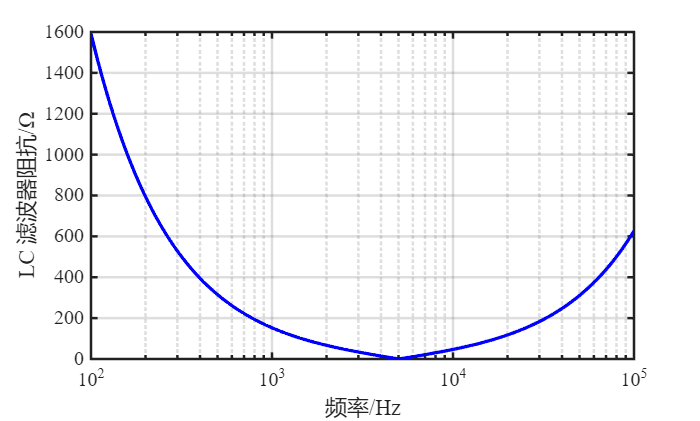

figure
L=1e-3;
C=1e-6;
f=linspace(1e2,1e5,1e5);
w=2*pi*f;
%%LC 滤波器
Z=(w*L-1./(w*C));
semilogx(f,abs(Z),'-b',"LineWidth",2)
grid on;
xlabel('频率/Hz')
ylabel('LC 滤波器阻抗/Ω')
set(gca,'LineWidth',1.5,'FontSize',12);

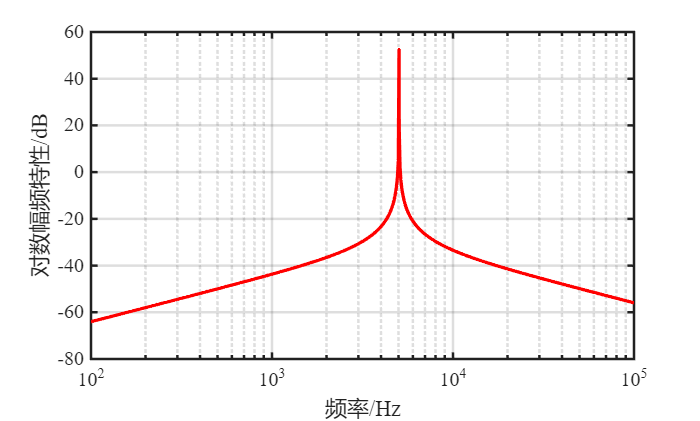

H=1./((L*C*(1j*w).^2+1)./(1j*w*C));
semilogx(f,20*log10(abs(H)),'-r',"LineWidth",2)
grid on;
xlabel('频率/Hz')
ylabel('对数幅频特性/dB')
set(gca,'LineWidth',1.5,'FontSize',12);

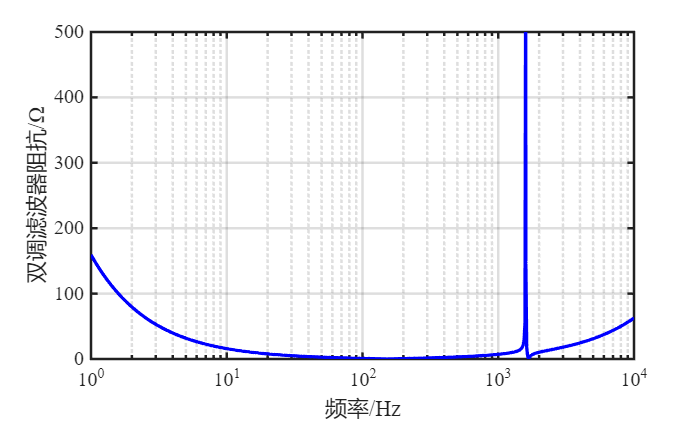

%%双调谐滤波器
f=linspace(1e0,1e4,1e5);
w=2*pi*f;
L1=1e-3;
C1=1e-3;
L2=1e-4;
C2=1e-4;
s=1j*w;
Z=s*L1+1./(s*C1)+1./(1./(s*L2)+s*C2);
semilogx(f,abs(Z),'-b',"LineWidth",2)
grid on;
xlabel('频率/Hz')
ylabel('双调滤波器阻抗/Ω')
set(gca,'LineWidth',1.5,'FontSize',12);
ylim([0,500])

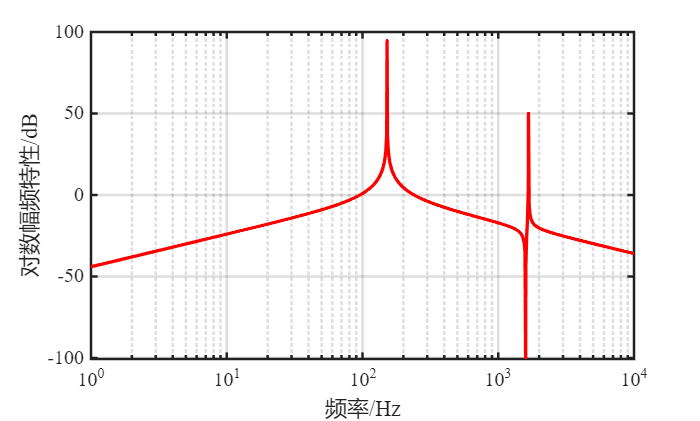

H=1./Z;
semilogx(f,20*log10(abs(H)),'-r',"LineWidth",2)
grid on;
xlabel('频率/Hz')
ylabel('对数幅频特性/dB')
set(gca,'LineWidth',1.5,'FontSize',12);

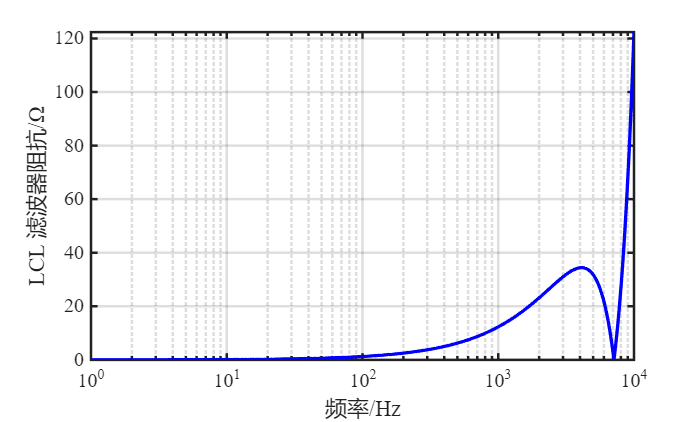

%%LCL 滤波器
f=linspace(1e0,1e4,1e5);
w=2*pi*f;
s=1j*w;
L1=1e-3;
L2=L1;
C=1e-6;
Z=s.^3*L1*L2*C+s*(L1+L2);
semilogx(f,abs(Z),'-b',"LineWidth",2)
grid on;
xlabel('频率/Hz')
ylabel('LCL 滤波器阻抗/Ω')
set(gca,'LineWidth',1.5,'FontSize',12);
ylim([0,max(abs(Z))])

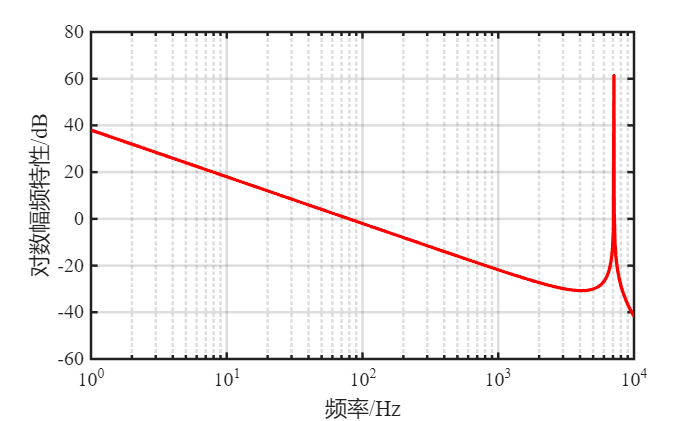

H=1./Z;
semilogx(f,20*log10(abs(H)),'-r',"LineWidth",2)
grid on;
xlabel('频率/Hz')
ylabel('对数幅频特性/dB')
set(gca,'LineWidth',1.5,'FontSize',12);

f=50;
w=2*pi*f;
f0=5*f;
w0=2*pi*f0;
C1=1e-5

C1 =                      1e-05


R1=0.001

R1 =                      0.001


L1=1/(w0*w0*C1)

L1 =         0.0405284734569351


f0=7*f;
w0=2*pi*f0;
C2=3e-6

C2 =                      3e-06


R2=0.001

R2 =                      0.001


L2=1/(w0*w0*C2)

L2 =         0.0689259752668965


f0=11*f;
w0=2*pi*f0;
C3=3e-4

C3 =                     0.0003


R3=0.001

R3 =                      0.001


L3=1/(w0*w0*C3)

L3 =       0.000279121718022969


f0=13*f;
w0=2*pi*f0;
C4=1e-4

C4 =                     0.0001


R4=0.001

R4 =                      0.001


L4=1/(w0*w0*C4)

L4 =        0.00059953363101975


f0=17*f;
w0=2*pi*f0;
C5=1e-3

C5 =                      0.001


R5=0.001

R5 =                      0.001


L5=1/(w0*w0*C5)

L5 =       3.50592330942345e-05


toc

历时 2.435383 秒。
